## Case Study: Chemical Test Strip (Numerical Integration)

## 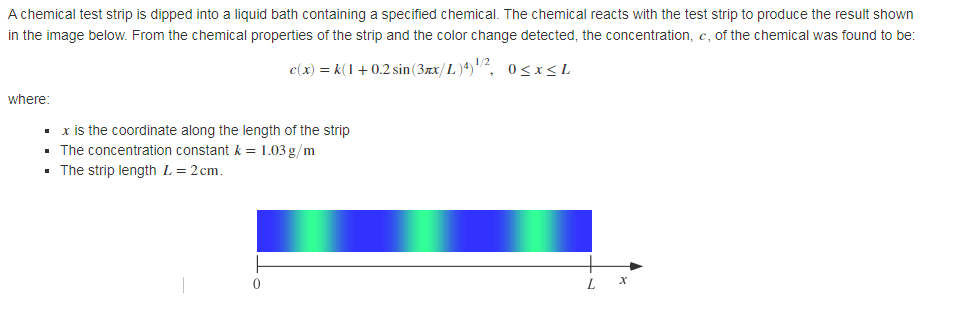

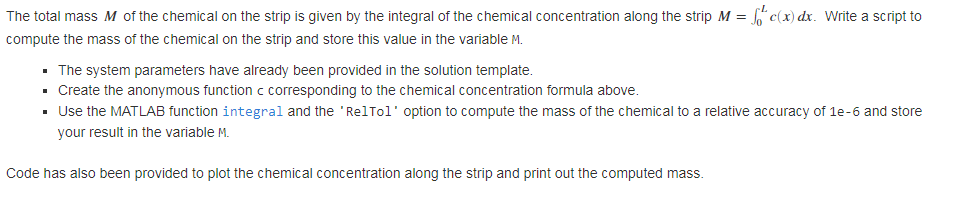

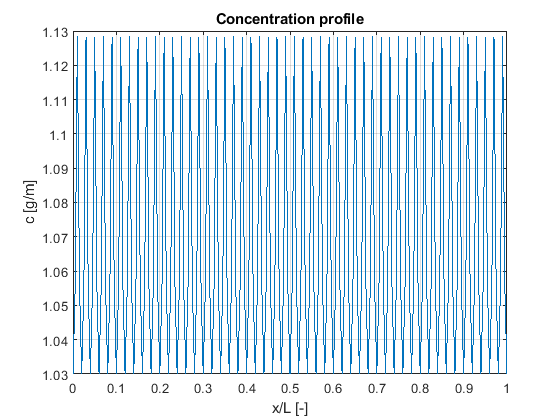

% Define the concentration parameters.
k = 1.03;                   % concentration minimum, [g/m]
L = 0.02;                   % strip length, [m]

% Define the concentration profile function. 
c = @(x) k*sqrt(1+0.2*sin((3*pi*x)/L).^4);

% Compute the mass of the chemical.
M = integral(c,0,L,'RelTol',1e-6);



%%%%%%%%%%% Plotting code below %%%%%%%%%%%%
% Plot the concentration profile.
z = linspace(a,b,201);
plot(z,c(z));
xlabel('x/L [-]');
ylabel('c [g/m]');
title('Concentration profile');
grid on;


% Print the result.
fprintf('mass of chemical = %.5f [g]\n',M);

mass of chemical = 0.02135 [g]
